# Systematic review of SysID

## Part 1. Prediction error minimization --- 2-DoF mass-spring-dampler system

Define stiffness and mass matrices

|\/\/\/\/\O\/\/\/\/\O

   k1 c1  m1  k2 c2  m2


$$M\ddot{X} +\textrm{C}\dot{X+} \textrm{KX}=F$$


clc;
clear;
close all;
m1=5; %mass 1 [kg]
m2=2; %mass 2 [kg]
k1=200; %spring 1 [N/m]
k2=100; %spring 2 [N/m]
c1=10; % damping coeff 1
c2=10; % damping coeff 2
M=[m1 0;0 m2]; %mass matrix
K=[k1+k2 -k2; -k2 k2]; %stiffness matrix
Damp=[c1+c2 -c2; -c2 c2]; % damping matrix

### 1.1 Load the data generated in script 1

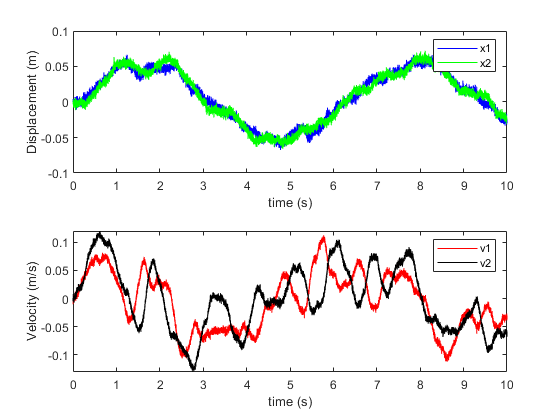

ysol = csvread(['2dof.csv']); %load data
T = 10; %length of time duration
nt = 10000; %number of time stamps
tspan=linspace(0,T,nt);
figure(1)
plot_dv(tspan,ysol')